#   Chapter 4, Section 3 (Part 1)

The goal of this activity is to introduce what is known as an isomorphism. Let's start with the definition of a one-to-one mapping.

# One-to-One Mapping

**Definition:** Let $V$ and $W$ be vector spaces and let $T:\,V \rightarrow W$ be a mapping. $T$ is a one-to-one linear transformation if $\vec u\ne\vec v$ implies that $T(\vec u)\ne T(\vec v)$. That is, different vectors in $V$ get sent to different vectors in $W$. A one-to-one mapping is also called **injective**.

Consider the following image.

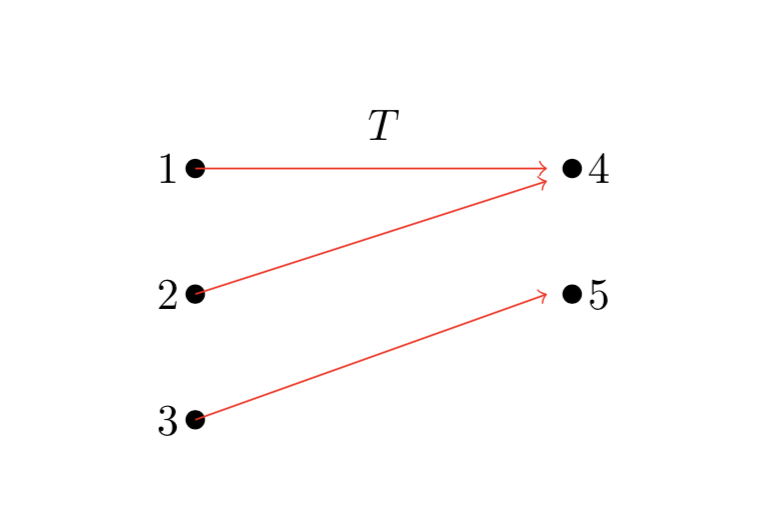

Note that on the left, 1 and 2 are different, but they both get set to the 4 on the right. Symbolically, this means that $1\ne 2$, but $T(1)=T(2)$, so this is **not** a one-to-one function. 

Here is a way to determine if a mapping is one-to-one that we will find extremely useful. A mapping is one-to-one if $T(\vec u)=T(\vec v)$ implies that $\vec u=\vec v$. Consider our image again. Note that $T(1)=T(2)$, but $1\ne 2$, so again, $T$ is not a one-to-one mapping. 

Now, let's do a linear algebra example.

# Example #1

Consider the linear transformation $T:\mathbb R^2\rightarrow\mathbb R^2$ defined by $T(\vec x)=A\vec x$, where


$$A=\pmatrix{1 & 2\cr 2 & 4}$$


Determine if $T$ is a one-to-one linear transformation. 

**Solution:** We've already shown that


$$\begin{array}{rcl}
T(\vec u+\vec v)&=&A(\vec u+\vec v)\\
&=&A\vec u+A\vec v\\
&=&T(\vec u)+t(\vec v)
\end{array}$$


and


$$\begin{array}{rcl}
T(c\vec u)&=&A(c\vec u)\\
&=&c(A\vec u)\\
&=&cT(\vec u)
\end{array}$$


so we know that any mapping of the form $T(\vec x)=A\vec x$ is a linear transformation. Now, is it one-to-one? Now, there are several ways that we can determine if $T$ is one-to-one. Consider the vectors


$$\vec u=\pmatrix{2\cr 0}\qquad\text{and}\qquad \vec v=\pmatrix{0\cr 1}$$


which are different; that is, $\vec u\ne \vec v$. But,


$$\begin{array}{rcl}
T(\vec u)&=&A\vec u\\
&=&\pmatrix{1 & 2\cr 2 & 4}\pmatrix{2\cr 0}\\
&=&\pmatrix{2\cr 4}
\end{array}$$


and:


$$\begin{array}{rcl}
T(\vec v)&=&A\vec v\\
&=&\pmatrix{1 & 2\cr 2 & 4}\pmatrix{0\cr 1}\\
&=&\pmatrix{2\cr 4}
\end{array}$$


Thus, $\vec u\ne \vec v$, but $T(\vec u)=T(\vec v)$, so this is **not** a one-to-one linear transformation. Some might ask how we came up with our choices for $\vec u$ and $\vec v$. The answer is that the columns of $A$ are linearly dependent, one is a multiple of the other, so we immediately thought that this would not be one-to-one and made our choices to show that it is not one-to-one. 

Here is another idea. Let's use Matlab to find the nullspace of $A$.

A=[1 2;2 4];
null(sym(A))

$$ans = \left(\begin{array}{c} -2\\ 1 \end{array}\right)$$

So, $B_{N(T)}=\left\{\pmatrix{-2\cr 1}\right\}$ is a basis for the nullspace of our linear transformation $T$. So, any multiple of this vector will get set to $\vec 0$ in $W$ by $T$.  Thus,


$$\begin{array}{rcl}
T\left(\pmatrix{-2\cr 1}\right)&=&\pmatrix{1 & 2\cr 2 & 4}\pmatrix{-2\cr 1}\\
&=&\pmatrix{0\cr 0}
\end{array}$$


and:


$$\begin{array}{rcl}
T\left(\pmatrix{-4\cr 2}\right)&=&\pmatrix{1 & 2\cr 2 & 4}\pmatrix{-4\cr 2}\\
&=&\pmatrix{0\cr 0}
\end{array}$$


Thus, two different vectors get sent to $\vec 0$, so our linear transformation $T$ is not one-to-one. This example gives us nice preparation for our first theorem. Before we state and prove our theorem, recall that we have shown that if $T$ is a linear transformation, then:

/$\begin{array}{rcl}
T(\vec 0)&=&T(\vec 0+\vec 0)\\
T(\vec 0)&=&T(\vec 0)+T(\vec 0)\\
T(\vec 0)&=&\vec 0
\end{array}$

# Theorem

The linear transformation $T:\, V\rightarrow W$ is one-to-one if and only if $N(T)=\{\vec 0\}$. 

**Proof:** Because this is an "if and only if" theorem, we have two things we need to prove.

- If $T:\, V\rightarrow W$ is one-to-one, then$N(T)=\{\vec 0\}$.

- If $N(T)=\{\vec 0\}$, then $T:\, V\rightarrow W$ is one-to-one.

**Part 1: **Assume that $T:\,V\rightarrow W$ is a one-to-one linear transformation. Recall from above that if $T$ is one-to-one, then $T(\vec u)=T(\vec v)$ implies that $\vec u=\vec v$.  Now, let $\vec v\in N(T)$. This means that


$$T(\vec v)=\vec 0$$


Because $T$ is one-to-one,  we can write:


$$\begin{array}{rcl}
T(\vec v)&=&T(\vec 0)\\
\vec v&=&\vec 0
\end{array}$$


Therefore, the only vector in the nullspace of $T$ is the zero vector, so we've shown that $N(T)=\{\vec 0\}$. 

**Part 2: **Assume that $N(T)=\{\vec 0\}$. Now, let


$$T(\vec u)=T(\vec v)$$


Because $T$ is a linear transformation, we can write:


$$\begin{array}{rcl}
T(\vec u)-T(\vec v)&=&\vec 0\\
T(\vec u-\vec v)&=&\vec 0
\end{array}$$


This tells us that $\vec u-\vec v$ is in the nullspace of $T$. Because $N(T)=\{\vec 0\}$, this means that $\vec u-\vec v$ is the zero vector and we can write:


$$\begin{array}{rcl}
\vec u-\vec v&=&\vec 0\\
\vec u&=&\vec v
\end{array}$$


Therefore, we've shown that $T(\vec u)=T(\vec v)$ implies that $\vec u=\vec v$, so we have shown that $T$ is one-to-one.

# Example #2

Let $T:\,P_2\rightarrow P_2$ be defined by $T(p(x))=p'(x)+2p(x)$. Given that this is a linear transformation, show that it is a one-to-one linear transformation. 

**Solution:** We'll use our theorem and investigate the null space of this transformation. Because $N(T)=\{p(x)\in P_2:\, T(p(x))=0\}$, we'll start with a polynomial $p(x)\in P_2$.


$$p(x)=a_0+a_1x+a_2x^2$$


Therefore,


$$\begin{array}{rcl}
T(p(x))&=&p'(x)+2p(x)\\
T(p(x))&=&(a_1+2a_2x)+(2a_0+2a_1x+2a_2x^2)\\
T(p(x))&=&(2a_0+a_1)+(2a_1+2a_2)x+2a_2x^2
\end{array}$$


Now, in order that $T(p(x))=0$, compare coefficients of


$$\begin{array}{rcl}
T(p(x))&=&0\\
(2a_0+a_1)+(2a_1+2a_2)x+2a_2x^2&=&0+0x+0x^2
\end{array}$$


gives us a system of three equations.


$$\begin{array}{rcl}
2a_0+a_1&=&0\\
2a_1+2a_2&=&0\\
2a_2&=&0
\end{array}$$


It is very easy to see that $a_1=a_2=a_3=0$, so the only polynomial $N(T)$ is the zero polynomial. Hence, by our theorem, the linear transformation $T$ is one-to-one.

Can we check our work with Matlab? The answer is "Yes." We enter our polynomial $p(x)=a_0+a_1x+a_2x^2$,, then take its tranformation.

syms a0 a1 a2 x
p=a0+a1*x+a2*x^2;
Tp=diff(p,x)+2*p

$$Tp = 2\,a_{0}+a_{1}+2\,a_{1}\,x+2\,a_{2}\,x+2\,a_{2}\,x^{2}$$

That's the same as our hand-calculations. Now, Matlab's **coeffs** command will return the coefficients of a polynomial. Entering coeffs(Tp,x) means we want the coefficients of the x-terms.

cfs=coeffs(Tp,x)

$$cfs = \left(\begin{array}{ccc} 2\,a_{0}+a_{1} & 2\,a_{1}+2\,a_{2} & 2\,a_{2} \end{array}\right)$$

It is more helpful to perform this last task as follows:

[cfs,terms]=coeffs(Tp,x)

$$cfs = \left(\begin{array}{ccc} 2\,a_{2} & 2\,a_{1}+2\,a_{2} & 2\,a_{0}+a_{1} \end{array}\right)$$

$$terms = \left(\begin{array}{ccc} x^{2} & x & 1 \end{array}\right)$$

This tells use that $2a_2$ is the coefficient of $x^2$, $2a_1+2a_2$ is the coefficient of $x$, and $2a_0+a_1$ is the coefficient of 1. Now, here is how we can equate each of these coefficients to zero (as we did above in our hand-calculations) and solve for $a_0$, $a_1$, and $a_2$.

[a0,a1,a2]=solve(cfs==[0,0,0],[a0,a1,a2])

$$a0 = 0$$

$$a1 = 0$$

$$a2 = 0$$

Wow! All the coefficients are zero as in our hand-calculations above, so we have done this problem properly. :-)

# Onto Mapping

Here is a definition of what is known as an onto mapping.

**Definition: ** Let $V$ and $W$ be vector spaces and let $T:\,V \rightarrow W$ be a mapping. T is onto $W$ if $R(T)=W$. 

This means that for any vector $\vec w\in W$, there exists a $\vec v\in V$ such that $T(\vec v)=\vec w$. A mapping that is onto is also called **surjective**. A mapping that is both one-to-one and onto is called an **bijective** mapping.

# Example #3

Let $T:\,\mathbb R^3\rightarrow\mathbb R^3$ be defined by


$$T\left(\pmatrix{x\cr y\cr z}\right)=\pmatrix{x+y+2z\cr x+2y+3z\cr x+y+2z}$$


Is this mapping onto $\mathbb R^3$?

**Solution: **This mapping can be written as


$$T\left(\pmatrix{x\cr y\cr z}\right)=\pmatrix{1 & 1 & 2\cr 1 & 2 & 3\cr 1 & 1 & 2}\pmatrix{x\cr y\cr z}$$


so it has the form $T(\vec x)=A\vec x$ and it is a linear transformation. Now, let's see if it is onto $\mathbb R^3$. Let $(a,b,c)^T$ be a vector in $\mathbb R^3$. Can we find a vector in $\mathbb R^3$, such that


$$T\left(\pmatrix{x\cr y\cr z}\right)=\pmatrix{a\cr b\cr c}$$


This is equivalent to:


$$\pmatrix{1 & 1 & 2\cr 1 & 2 & 3\cr 1 & 1 & 2}\pmatrix{x\cr y\cr z}=\pmatrix{a\cr b\cr c}$$


Set up the augmented matrix and row reduce.


$$\pmatrix{1 & 1 & 2 & a\cr 1& 2 & 3 & b\cr 1 & 1 & 2 & c}\ \matrix{~\cr R_2-R_1\cr R_3-R_1}\qquad\longrightarrow\qquad\pmatrix{1 & 1 & 2 & a\cr 0& 1 & 1 & b-a\cr 0 & 0 & 0 & c-a}$$


We can check this step with Matlab.

syms a b c
A=[1 1 2 a;1 2 3 b;1 1 2 c]

$$A = \left(\begin{array}{cccc} 1 & 1 & 2 & a\\ 1 & 2 & 3 & b\\ 1 & 1 & 2 & c \end{array}\right)$$

Looks good. Now,

r1=A(1,:);
r2=A(2,:);
r3=A(3,:);
A=[r1;r2-r1;r3-r1]

$$A = \left(\begin{array}{cccc} 1 & 1 & 2 & a\\ 0 & 1 & 1 & b-a\\ 0 & 0 & 0 & c-a \end{array}\right)$$

Same as our hand-calculated answer. Now, the third row represents


$$0x+0y+0z=c-a$$


which has no solutions if $c-a\ne 0$. Therefore, our system has solutions only if $c-a=0$, which means that $T$ is not onto $\mathbb R^3$. 

Let's visualize this result. If $c-a=0$, then $a=c$, and we can write:


$$\begin{array}{rcl}
\pmatrix{a\cr b\cr c}&=&\pmatrix{c\cr b\cr c}\\
\pmatrix{a\cr b\cr c}&=&\pmatrix{c\cr 0\cr c}+\pmatrix{0\cr b\cr 0}\\
\pmatrix{a\cr b\cr c}&=&c\pmatrix{1\cr 0\cr 1}+b\pmatrix{0\cr 1\cr 0}
\end{array}$$


Thus, the range of $T$ is all linear combinations of the linearly independent vectors $(1,0,1)^T$ and $(0,1,0)^T$. Some might be confused by this statement saying "I thought the range of this transformation is the column space of $A$, which is spanned by the linearly independent columns one and two of matrix $A$, that is, $(1,1,1)^T$ and $(1,2,1)^T$." However, note that


$$\pmatrix{1\cr 0\cr 1}=2\pmatrix{1\cr 1\cr 1}-1\pmatrix{1\cr 2\cr 1}$$


and


$$\pmatrix{0\cr 1\cr 0}=-1\pmatrix{1\cr 1\cr 1}+1\pmatrix{1\cr 2\cr 1}$$


so these two linearly independent vectors lie in the span of the column space, so they also span the range of our transformation. Now, let's use the vectors $(1,0,1)^T$ and $(0,1,0)^T$ to sketch the range of our transformation.


$$\pmatrix{x\cr y\cr z}=c\pmatrix{1\cr 0\cr 1}+b\pmatrix{0\cr 1\cr 0}=\pmatrix{c\cr b\cr c}$$


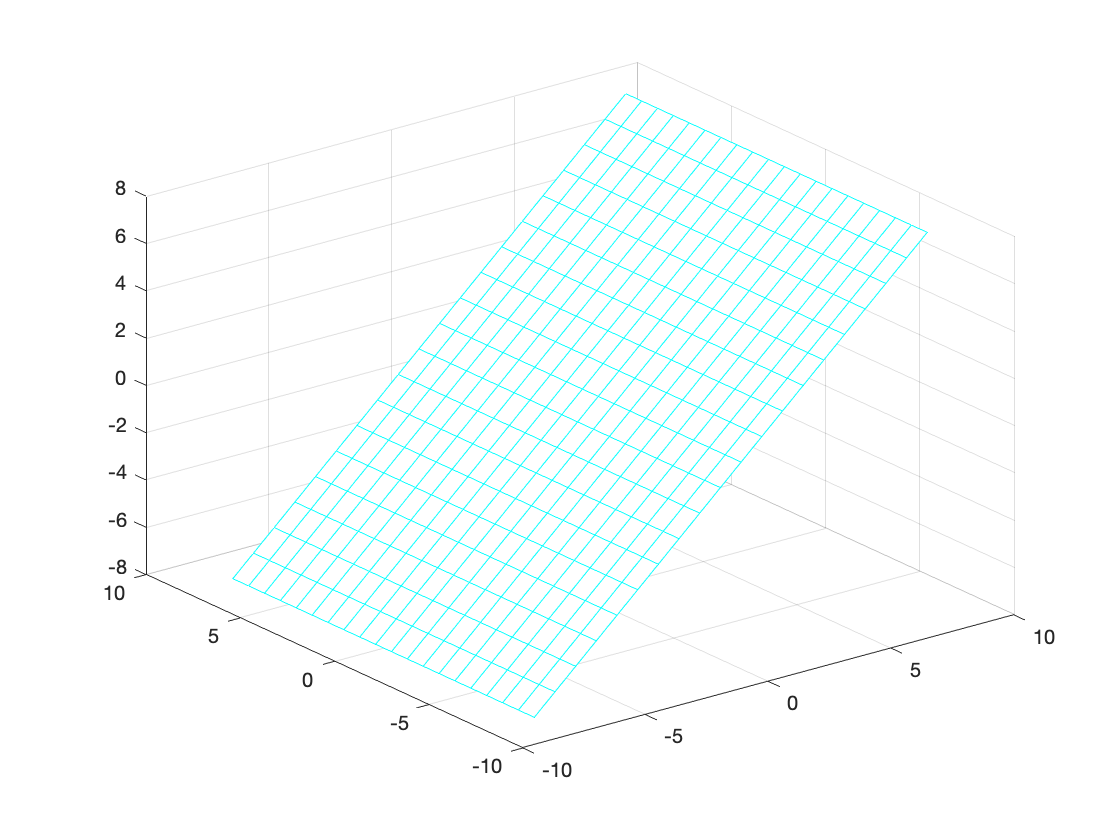

figure
b=linspace(-8,8,20);
c=linspace(-8,8,20);
[B,C]=meshgrid(b,c);
X=C;
Y=B;
Z=C;
mesh(X,Y,Z,'EdgeColor','c')
hold on

Now, let's draw a whole bunch of points in $\mathbb R^3$.

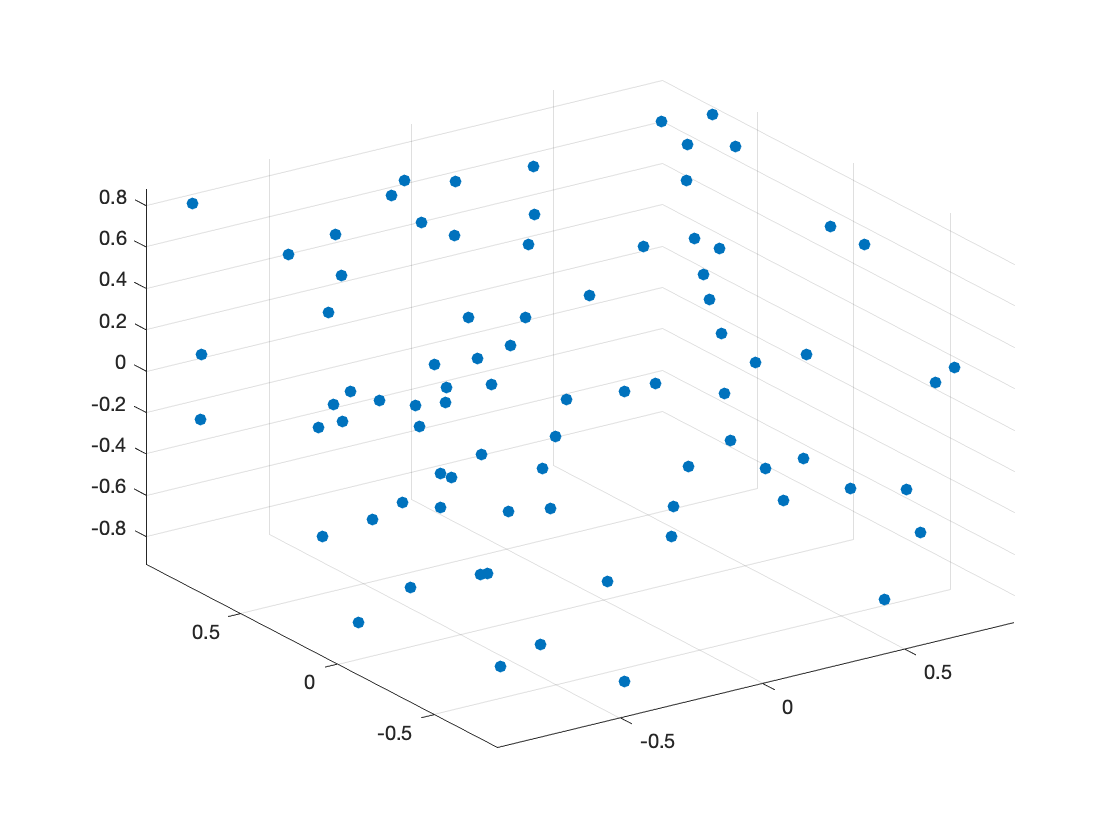

figure
x=1-2*rand(1,100);
y=1-2*rand(1,100);
z=1-2*rand(1,100);
scatter3(x,y,z,'filled')

If you rotate this image, you'll see that these points do not lie on a plane, but are scattered throughout $\mathbb R^3$. Now, let's transform these points with $T(\vec x)=A\vec x$ and see where they land.

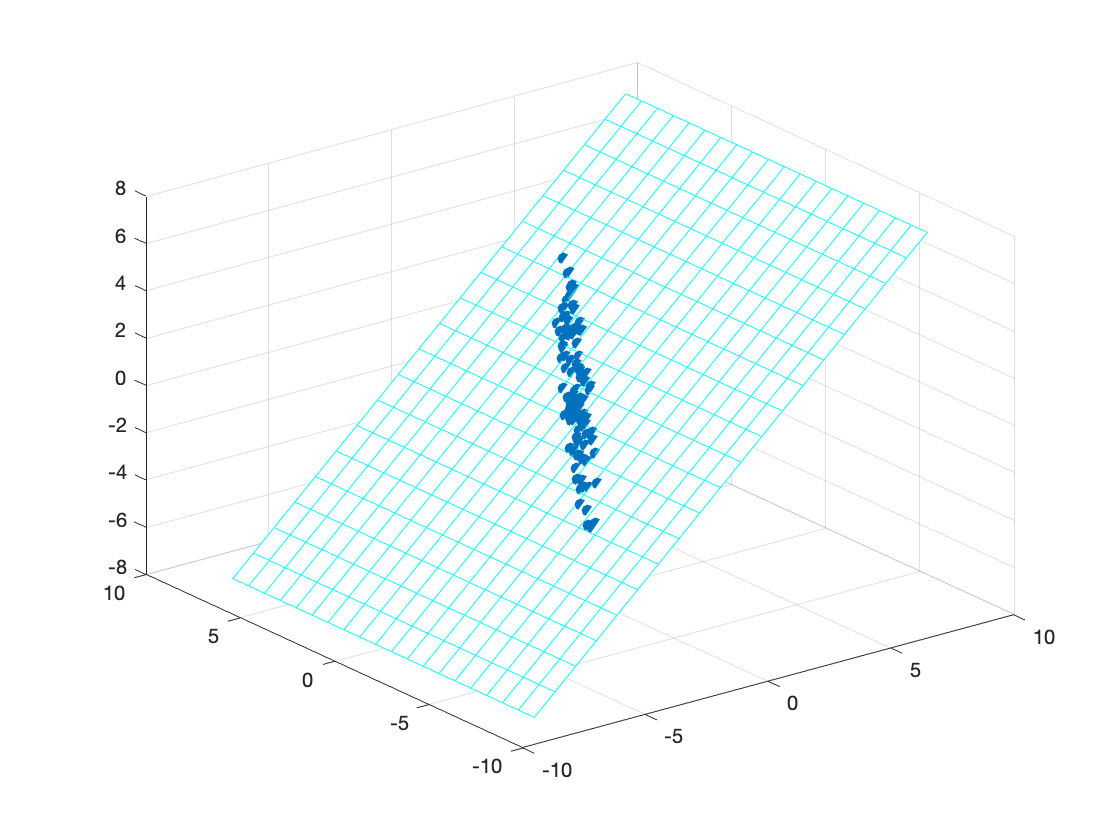

figure
b=linspace(-8,8,20);
c=linspace(-8,8,20);
[B,C]=meshgrid(b,c);
X=C;
Y=B;
Z=C;
mesh(X,Y,Z,'EdgeColor','c')
hold on
pts=[x;y;z];
A=[1 1 2;1 2 3;1 1 2];
Tpts=A*pts;
scatter3(Tpts(1,:),Tpts(2,:),Tpts(3,:),'filled')
hold off

They all lie on our plane, so this is clear visual evidence that this linear transformation is **not** onto all of $\mathbb R^3$.